# Representative Signal Chain

## User parameters

% Camera
p.fl    = 0.5;      %[m] focal length
p.Dapp  = 0.1;      %[m] Apperture Diameter
p.p     = 5e-6;     %[m] pixel pitch
p.cnt   = 2e3;      %[#] sqrt of number of pixels
p.Rate  = [3,50]    %[hz] frame rate of imagery

p = struct with fields:
        fl: 0.5000
      Dapp: 0.1000
         p: 5.0000e-06
       cnt: 2000
      Rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
      rImg: 30000
    rStart: 840000
      Dtgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     lPOCA: [0 7000000 0]


p.int   = [5e-2,1e-3] %[s] integration time

p = struct with fields:
        fl: 0.5000
      Dapp: 0.1000
         p: 5.0000e-06
       cnt: 2000
      Rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
      rImg: 30000
    rStart: 840000
      Dtgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     lPOCA: [0 7000000 0]


p.bgIrr = 1e-6;     %[w/m2/bp] Irradiance on the FP, ideally this would be from a series of simulation 
p.cwl   = 600e-9;   %[m] center wavelength
p.bp    = 400e-9;   %[m] bandpass width

% engagement
p.engPhs= 45;   %[deg] Phase angle between sensor and target velocity vectors
p.POCA  = 5e3;  %[m] Seperation of target and sensor at point of closest approach
p.lPOCA = [0,7000e3,0]%[m] Locating Poca location

p = struct with fields:
        fl: 0.5000
      Dapp: 0.1000
         p: 5.0000e-06
       cnt: 2000
      Rate: [3 50]
       int: [0.0500 1.0000e-03]
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
    engPhs: 45
      POCA: 5000
      rImg: 30000
    rStart: 840000
      Dtgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     lPOCA: [0 7000000 0]


p.rImg  = 30e3; %[s] range which we switch integration 
p.rStart= 840e3;%[m] range from Poca we start the engagement
p.Dtgt  = 5;    %[m] Diameter of target
p.rfl   = 1;    %[ratio] reflectance   


% Simulation Params
p.mBuf  = 10;   %[pixels] How much motion we'll allow
p.strOSF= 17;   %[scl] determines how much we'll oversample the psf for the stars
p.tgtOSF= 3;    %[tgt] determines how much we'll over sample the target
p.bgShp = .4;   %[] drives how quickly the SL falls off >1 quicker, <1 slower, 1 = radially
p.maxMag= 13;    %[] drives max mag of those stars (3x drop in stars/mag)

## Read in data and create LUTs

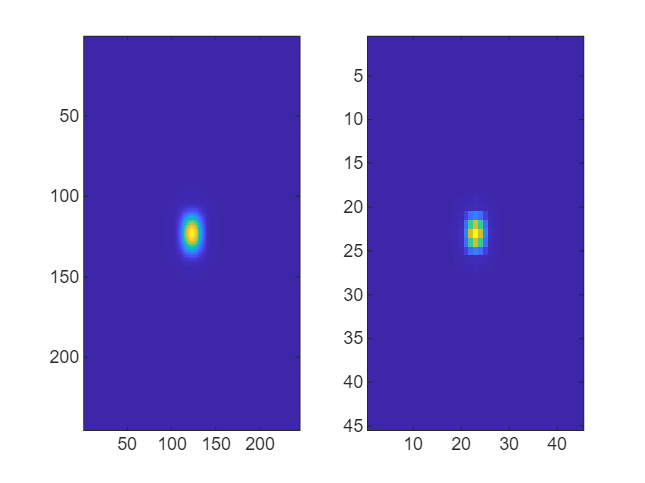

%Make representative SL Im (Ideally this comes from somewhere else, like a
%SL LUT dependant on sun and earth angles + zodiacal)
[x,y]   = meshgrid(linspace(-1,1,p.cnt),linspace(-1,1,p.cnt));
r       = 1-sqrt(x.^2+y.^2); r = r-min(r(:));;
s.bg    = p.bgIrr*abs(r/max(r(:)).^p.bgShp);
if 0; imagesc(abs(r.^p.bgShp)); end; %for testing

% Generate a PRP for our stars (Note: for a system with a changing Focus to
% keep up with the target, this would be an LUT)
[psf, x, y] = diffraction_psf(p.p/p.strOSF, p.fl/p.Dapp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.strOSF),'same'); %turn it into a prp
s.strPRP = padarray(prp0,[1 1]*round(p.mBuf *p.strOSF/2),0,'both'); %pad array for motion

%Do the same thing for our target. (Note: This should be an LUT based on
%the focus of the system and the range of the target)
[psf, x, y] = diffraction_psf(p.p/p.tgtOSF, p.fl/p.Dapp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.tgtOSF),'same'); %turn it into a prp
s.tgtPRP = padarray(prp0,[1 1]*round(p.mBuf *p.tgtOSF/2),0,'both'); %pad array for motion
if 1; subplot(1,2,1);imagesc(s.strPRP);subplot(1,2,2);imagesc(s.tgtPRP); end;


%Generate a star LUT
fov = p.p*p.cnt/p.fl*180/pi

fov = 1.1459

s.starLUT = star_lut(p.maxMag,1,fov); %This will just give a rough

res = 0.0100

samples =    13.0000   12.9900   12.9800   12.9700   12.9600   12.9500   12.9400   12.9300   12.9200   12.9100   12.9000   12.8900   12.8800   12.8700   12.8600   12.8500   12.8400   12.8300   12.8200   12.8100   12.8000   12.7900   12.7800   12.7700   12.7600   12.7500   12.7400   12.7300   12.7200   12.7100   12.7000   12.6900   12.6800   12.6700   12.6600   12.6500   12.6400   12.6300   12.6200   12.6100   12.6000   12.5900   12.5800   12.5700   12.5600   12.5500   12.5400   12.5300   12.5200   12.5100


fovScl = 2.0264e-05


%get sun irrad
dat = readtable('SolarSpec.txt');
wl = dat.Wavelength_nm_*1e-9;
idx = find((wl>(p.cwl-p.bp/2))==(wl<(p.cwl+p.bp/2)));
s.sun = trapz(dat.Wavelength_nm_(idx),dat.Extraterrestrial_W_m2_nm_(idx));

## Generate engagements

vSens   = [-7e3,0,0]
vTgt    = [cosd(p.engPhs),0,sind(p.engPhs)]*-7e3

%calc engagement range
xSens(1,:) = p.lPOCA+[p.rStart, 0, 0];
xTgt(1,:)  = p.lPOCA+[cosd(p.engPhs)*p.rStart,-p.POCA,sind(p.engPhs)*p.rStart];
mode = 1
i = 1
t(1) = 0
while mode ~=3
    i = i+1
    tMode(i)   = mode;
    t(i)       = t(i-1)+1/p.Rate(mode);    
    xSens(i,:) = xSens(i-1,:)+vSens.*1/p.Rate(mode);
    xTgt(i,:)  = xTgt(i-1,:)+vTgt.*1/p.Rate(mode);
    if mode == 1 && norm(xTgt(i,:)-p.lPOCA)<p.rImg
        mode = mode +1
    elseif mode == 2 && norm(xTgt(i,:)-p.lPOCA)>p.rImg
        mode = mode +1
    end
end
    
    
%% Get Pointing
dx  = xTgt - xSens;
dv  = repmat(vTgt - vSens,[length(dx),1]);
los = dx(:,1:3) ./ vecnorm(dx(:,1:3),2,2);
omega   = cross(dx(:,1:3),dv,2) ./ dot(dx(:,1:3),dv,2);
omega_poca = omega ./ sqrt(sum(omega.^2, 2));
oz_des  = omega_poca;
oy_des  = cross(oz_des, los, 2); oy_des = oy_des ./ vecnorm(oy_des,2,2);
ox_des  = cross(oy_des, oz_des, 2);
R_desHat= pagetranspose(reshape([ox_des oy_des oz_des]',3,3,[]));
tQ      = dcm2quat(R_desHat); %direction cosine matric to quaternions

% Get RaDec for stars
opticAx = quatrotate(quatconj(tQ),[1,0,0]);
tRadDec = [atan2(opticAx(:,2),opticAx(:,1)),...
    asin(opticAx(:,3))];
tRadDec(tRadDec(:,1)<0,1) = tRadDec(tRadDec(:,1)<0,1)








## Functions

% Generate a psf
function [psf, x, y] = diffraction_psf(pixel_pitch, f_number, wavelength)
    % Generates the diffraction-limited point spread function (PSF).
    
    % Input arguments:
    %   pixel_pitch: Pixel pitch in meters.
    %   f_number: f-number of the optical system.
    %   wavelength (optional): Wavelength of light in meters. Defaults to 550nm.
    
    % Output arguments:
    %   psf: The PSF array.
    %   x: The x-coordinates of the PSF grid.
    %   y: The y-coordinates of the PSF grid.
    
    if nargin < 3
        wavelength = 550e-9; % Default wavelength: green light
    end
    
    % Calculate the Airy disk radius (first minimum)
    airy_radius = 1.22 * wavelength * f_number;
    
    % Create a grid for the PSF
    psf_size = ceil(6 * airy_radius / pixel_pitch); % Size of the PSF array
    if mod(psf_size, 2) == 0  % Ensure psf_size is odd for centering
        psf_size = psf_size + 1;
    end
    
    x = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    y = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    [X, Y] = meshgrid(x, y);
    r = sqrt(X.^2 + Y.^2);
    
    % Calculate the PSF using the Airy disk formula
    psf = zeros(size(r));
    nonzero_r = r > 0;
    psf(nonzero_r) = (2 * besselj(1, pi * r(nonzero_r) / airy_radius) ./ (pi * r(nonzero_r) / airy_radius)).^2;
    psf(r == 0) = 1.0; % Central maximum
    
    % Normalize the PSF (integral should be 1)
    psf = psf / sum(psf(:));
end

function starLUT = star_lut(mag,scl,FoV)
% This will just generate a random distribution of stars. For magnitudes,
% it uses the rough approximation that every order of magnitude yields a
% factor of 3 increase in the number of stars to create a PDF. 

% Input arguments:
%   mag: limits the maximum magnitude of stars
%   count: number of stars in total
%   FoV: size of the field of view, used to limit number of stars

% Output arguments:
%   a mock star catalog

%set up sampling
res     = 0.01
samples = mag-[0:res:mag]
%create a pdf using the approximation that every magnitude there are about
%3x as many stars
magPDF = 3.^((mag-[0:.01:mag]));
fovScl = FoV^2/(360*180) % a scale factor based on the average number of stars in a FoV
num_samples = round(sum(magPDF*res)*scl*fovScl);

%get number or magnitude quantizations
n_categories = length(magPDF);

% Create the cumulative distribution function (CDF).
cdf = cumsum(magPDF)/sum(magPDF);

% Generate uniform random numbers between 0 and 1.
random_numbers = rand(num_samples, 1);

% Initialize the output vector.
starLUT = zeros(num_samples, 3);

% Use CDF to distribute magnitudes appropriately
for i = 1:n_categories
  starLUT((random_numbers <= cdf(i)) == (starLUT(:,1)==0),1) = samples(i);  
end

starLUT(:,2) = rand(num_samples,1)*2048;
starLUT(:,3) = rand(num_samples,1)*2048;

end
